num=1;
den=[1 10 20];
g=tf(num,den)


g =
 
         1
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.



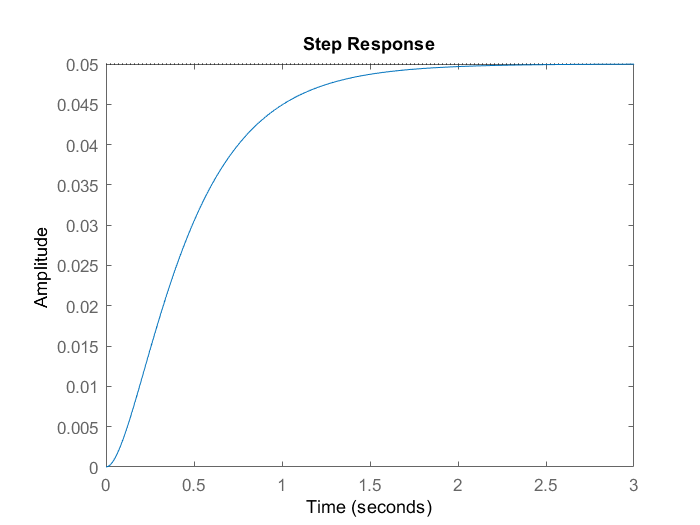

t=feedback(g,1);
step(g)

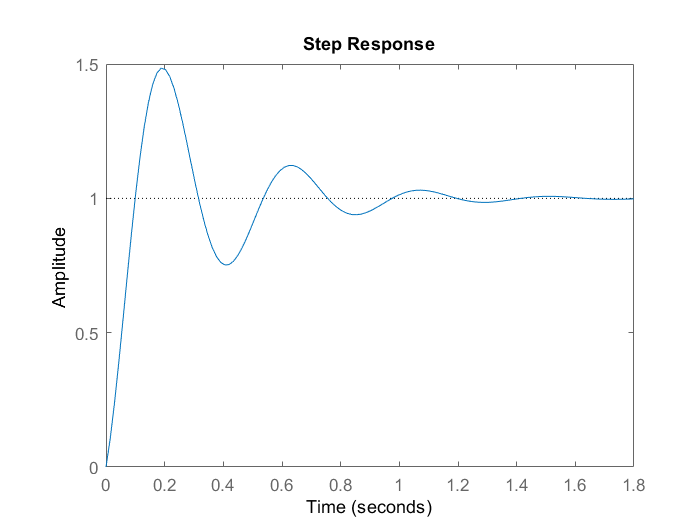


kp=256.712;
ki=2134.33;
kd=6.314;
cont=pid(kp,ki,kd);
step(feedback(cont*t,1));

stepinfo(feedback(cont*t,1))

ans = struct with fields:
        RiseTime: 0.0762
    SettlingTime: 1.1323
     SettlingMin: 0.7519
     SettlingMax: 1.4846
       Overshoot: 48.4638
      Undershoot: 0
            Peak: 1.4846
        PeakTime: 0.1883


k=dcgain(cont*t);
1/(1+k)

ans = 0